# Linear Predictors

## Forward Linear Predictors

**Problem:** we want predict the current signal value $\hat{x} \left\lbrack n\right\rbrack$ given a set of $p$ previous samples of a wide-sense stationary process:

        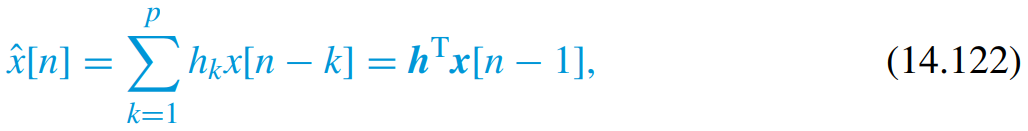

This is called one-step *forward linear predictor.*

The normal equations for the optimum linear predictor are:

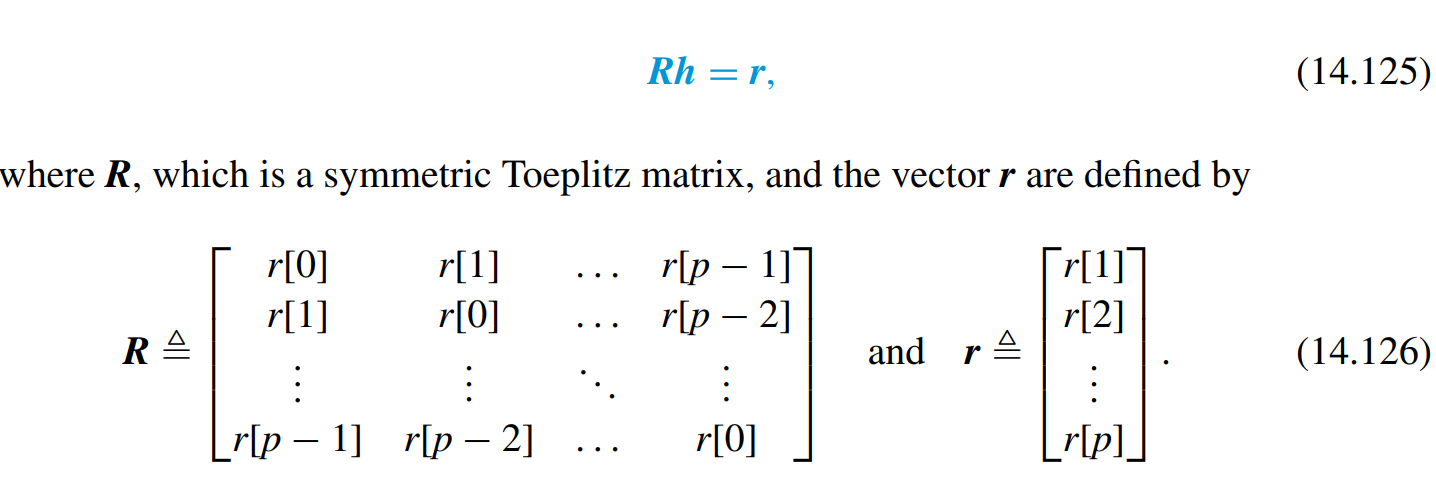

The minimum squared error is given by Eq. 14.127:

        

## All-pole signal modelling

Suppose the input signal $x\left\lbrack n\right\rbrack$ is an AR(p) model i.e.:

        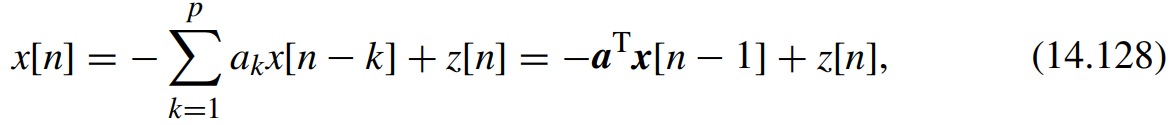

where $z\left\lbrack n\right\rbrack ~\mathrm{WN}\left(0,\sigma_z^2 \right)$

The value that we want to predict $x\left\lbrack n\right\rbrack$ can written as:

        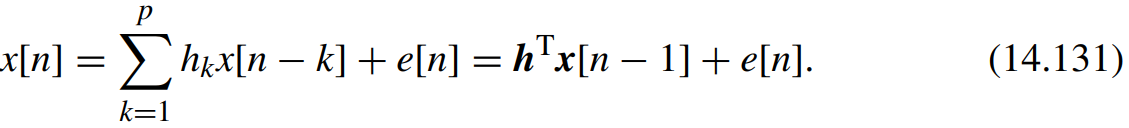

Setting $\mathit{\mathbf{h}}=-\mathit{\mathbf{a}}$, the prediction error can be expressed as:

        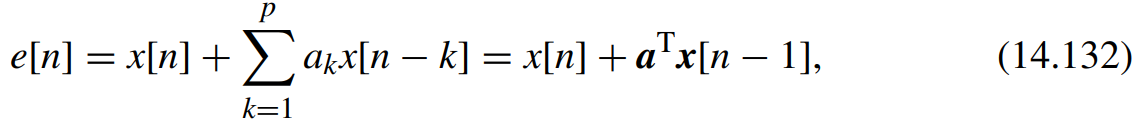

This shows that the prediction error $e\left\lbrack n\right\rbrack$ is the output of a filter with the following system function:

        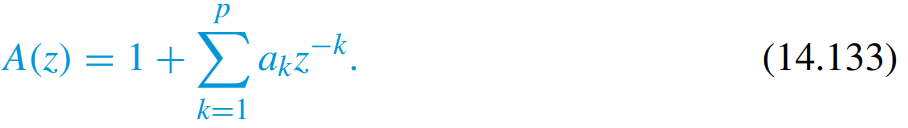

This system $A\left(z\right)$ is known as the ***prediction error filter*** or the ***analysis filter***.

If the input $x\left\lbrack n\right\rbrack$ is an AR(p) process, the output of $A\left(z\right)$ is a white noise process $z\left\lbrack n\right\rbrack$

## [✔] ADSI Problem 6.4: Linear interpolation, estimate missing samples

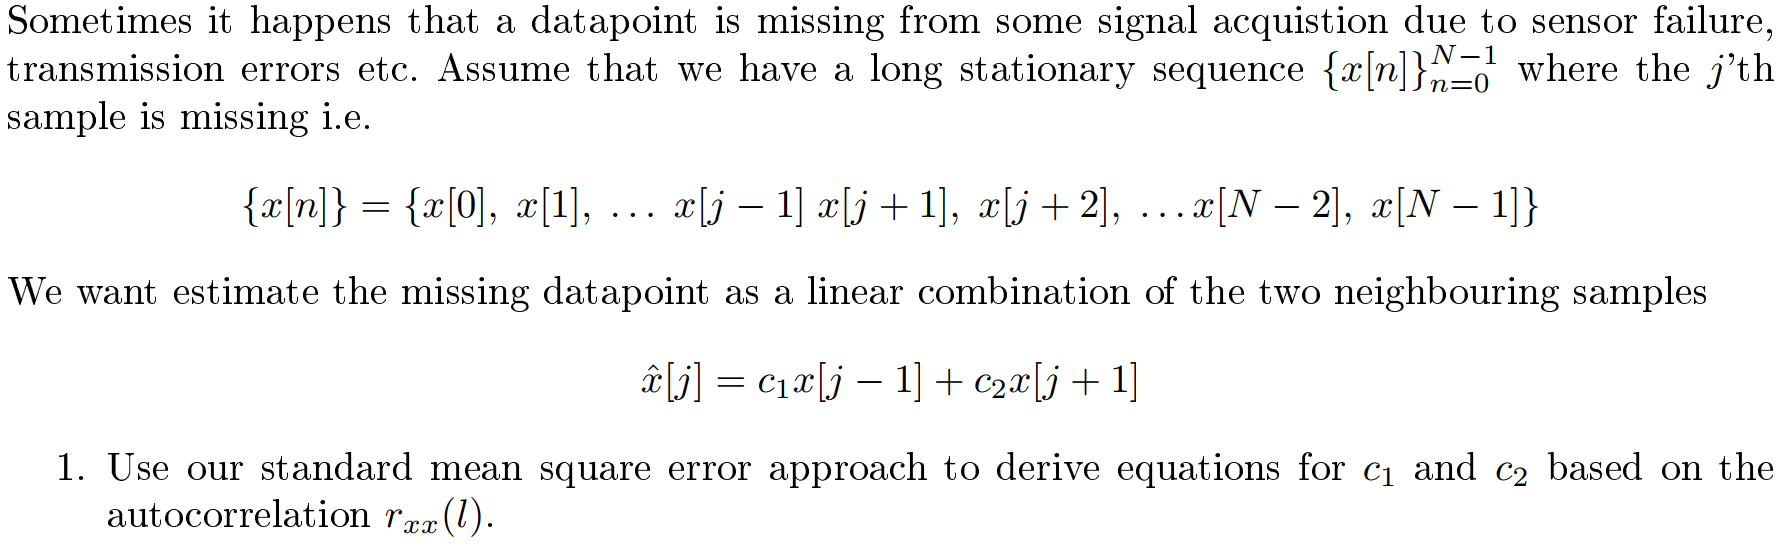

### 1) Use mean squared error to derive coefficients based on the ACRS

We want to estimate a missing sample $x\left(j\right)$ as a linar combination of two neighbouring samples:

        
$$\hat{x} \left(j\right)=c_1 x\left(j-1\right)+c_2 x\left(j+1\right)$$


To find the coefficients $c_1$ and $c_2$ using the mean squared error method, we need to take following steps:

- Find an expression for the error: $e\left(n\right)$

- Square the error quantity: $e^2 \left(n\right)$

- Take the expectation of squared error: $E\left\lbrack e^2 \left(n\right)\right\rbrack$ to find the Mean Squared Error

- Find the minimum by setting the partial derivatives of MSE to zero and solving the equation

Step 1: The error of the estimate is:

        
$$e\left(j\right)=x\left(j\right)-\hat{x} \left(j\right)$$


        
$$e\left(j\right)=x\left(j\right)-\left(c_1 x\left(j-1\right)+c_2 x\left(j+1\right)\right)$$


        
$$e\left(j\right)=x\left(j\right)-c_1 x\left(j-1\right)-c_2 x\left(j+1\right)$$


Step 2: square the error

        
$$e^2 \left(j\right)=\left(x\left(j\right)-c_1 x\left(j-1\right)-c_2 x\left(j+1\right)\right)\left(x\left(j\right)-c_1 x\left(j-1\right)-c_2 x\left(j+1\right)\right)$$


syms c1 c2 x_j x_jm1 x_jp1
expand((x_j - c1*x_jm1 - c2*x_jp1)^2)

$$ans = {c_{1}}^{2}\,{x_{\mathrm{jm1}}}^{2}+2\,c_{1}\,c_{2}\,x_{\mathrm{jm1}}\,x_{\mathrm{jp1}}-2\,c_{1}\,x_{j}\,x_{\mathrm{jm1}}+{c_{2}}^{2}\,{x_{\mathrm{jp1}}}^{2}-2\,c_{2}\,x_{j}\,x_{\mathrm{jp1}}+{x_{j}}^{2}$$

        
$$e^2 \left(j\right)=c_1^2 x^2 \left(j-1\right)+2c_1 c_2 x\left(j-1\right)x\left(j+1\right)-2c_1 x\left(j\right)x\left(j-1\right)+c_2^2 x^2 \left(j+1\right)-2c_2 x\left(j\right)x\left(j+1\right)+x^2 \left(j\right)$$


Step 3: Take the expectation of the squared error:

        
$$E\left\lbrack e^2 \left(j\right)\right\rbrack =E\left\lbrack c_1^2 x^2 \left(j-1\right)+2c_1 c_2 x\left(j-1\right)x\left(j+1\right)-2c_1 x\left(j\right)x\left(j-1\right)+c_2^2 x^2 \left(j+1\right)-2c_2 x\left(j\right)x\left(j+1\right)+x^2 \left(j\right)\right\rbrack$$


        
$$E\left\lbrack e^2 \left(j\right)\right\rbrack =c_1^2 E\left\lbrack x^2 \left(j-1\right)\right\rbrack +2c_1 c_2 E\left\lbrack x\left(j-1\right)x\left(j+1\right)\right\rbrack -2c_1 E\left\lbrack x\left(j\right)x\left(j-l\right)\right\rbrack$$


                          
$$+c_2^2 E\left\lbrack x^2 \left(j+1\right)\right\rbrack -2c_2 E\left\lbrack x\left(j\right)x\left(j+1\right)\right\rbrack +E\left\lbrack x^2 \left(j\right)\right\rbrack$$


From the expression, we observe different autocorrelation values:

        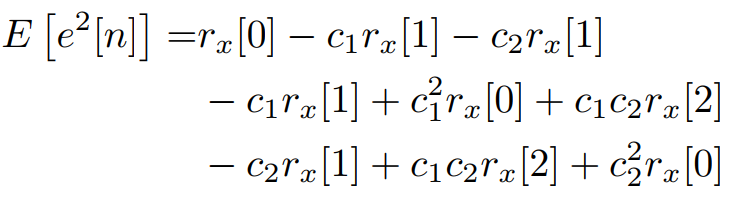

Step 4: The minimum is found by taking the partial derivatives, setting it zero and solving the two equations:

        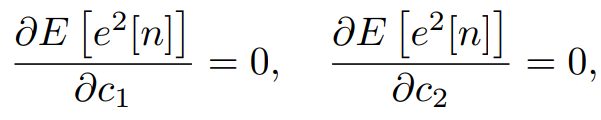

The partial derivatives become:

        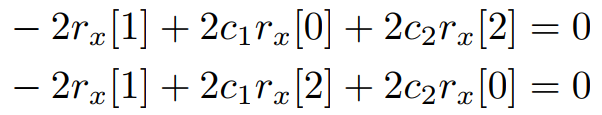

Which can be written as a matrix equation:

        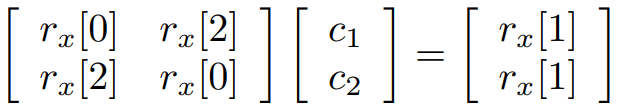

Working through the equations the solution is:

        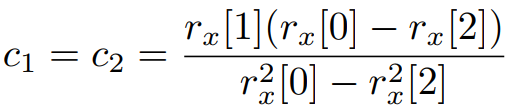

## [✔] ADSI Problem 6.6: Levinson-Durbin and linear prediction

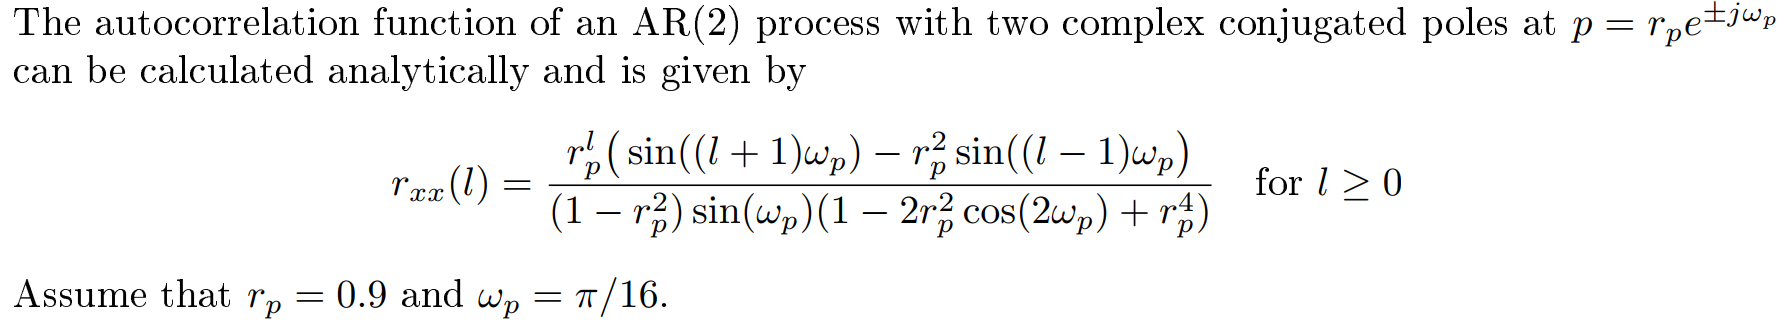

### [✔] 1) Plot the autocorrelation function.

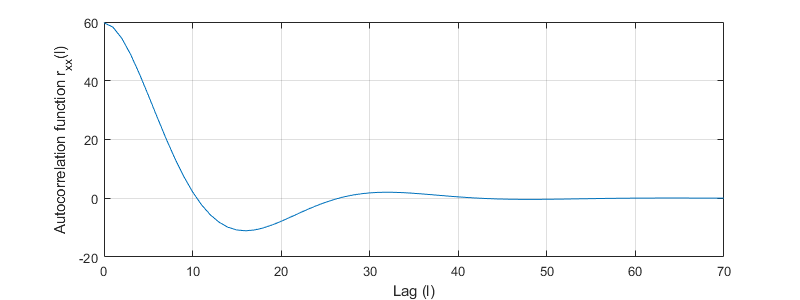

rp = 0.9;
wp = pi/16;

l = 0:70;

nominator = rp.^l.* (sin((l + 1)*wp) - rp^2*sin((l - 1)*wp));
denominator = (1 - rp^2) * sin(wp) * (1 - 2*rp^2*cos(2*wp) + rp^4);
r_xx = nominator / denominator;

figure('position', [0, 0, 800, 300])
plot(l, r_xx)
xlabel('Lag (l)')
ylabel('Autocorrelation function r_{xx}(l)')
grid on;

### [✔] 2) Compute reflection coefficients for m'th order optimum linear predictors

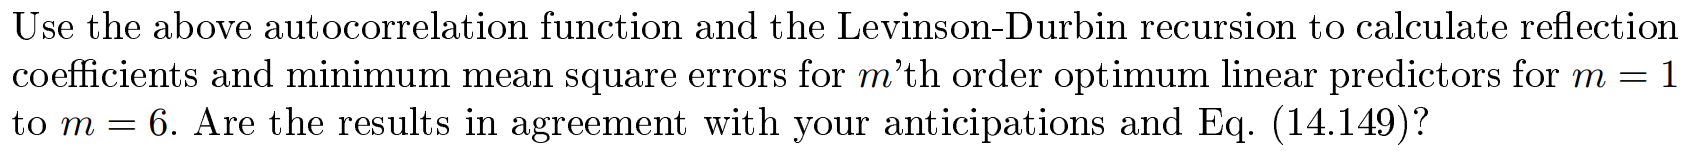

First, we use the MATLAB function `levinson(r_xx, m)` to compute the reflection coefficients and the corresponding errors for the different $m$'th order linear predictors:

M = 6;
err = zeros(M, 1); % Array to store the errors

for m=1:M
    [a, e, k] = levinson(r_xx, m);
    % `a` is the coefficients of the AR(m) model
    % `e` is the prediction error of m'th order optimimum linear predictor
    % `k` is the reflection coefficients of the linear predictor    
    err(m) = e;
    display(strcat('Coefficients for a', 32, num2str(m), '-th order predictor', 32))
    display(k)
end

Coefficients for a 1-th order predictor 


k = -0.9754

Coefficients for a 2-th order predictor 


k =    -0.9754
    0.8100


Coefficients for a 3-th order predictor 


k =    -0.9754
    0.8100
   -0.0000


Coefficients for a 4-th order predictor 


k =    -0.9754
    0.8100
   -0.0000
   -0.0000


Coefficients for a 5-th order predictor 


k =    -0.9754
    0.8100
   -0.0000
   -0.0000
    0.0000


Coefficients for a 6-th order predictor 


k =    -0.9754
    0.8100
   -0.0000
   -0.0000
    0.0000
   -0.0000


It is important to note that the reflection coefficients $\left\lbrace k_3 ,k_4 ,k_5 ,k_6 \right\rbrace$ are zero. This is to be expected as the reflection coefficients is dependent on the AR(q) model. Since we have an AR(2) model, the corresponding reflection coefficients become zero.

Let us consider the error of each of the predictors. Eq. 14.149 states that the prediction error can be calculated based on the previous error and current reflection coefficient:

        

where $J_0 =r_{\mathrm{xx}} \left(0\right)$ and $\beta_1 =r_{\mathrm{xx}} \left(1\right)$

The squared error should be 1 once the order of the predictor matches or exceeds the AR(q) model.

J0 = r_xx(1)

J0 = 59.7579

J1 = (1 - k(1)^2) * J0

J1 = 2.9078

J2 = (1 - k(2)^2) * J1

J2 = 1.0000

J3 = (1 - k(3)^2) * J2

J3 = 1.0000

Let us plot the order of the linear predictor versus the prediction error for an AR(2) model.

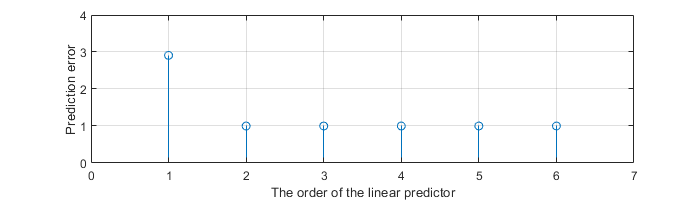

figure('position', [0, 0, 700, 200])
stem(err)
xlabel('The order of the linear predictor')
ylabel('Prediction error')
xlim([0, M+1])
ylim([0, 4])
grid on;

## [?] ADSI Problem 6.7: Linear prediction of a sine signal

This problem addresses linear prediction on a simple harmonic signal where the results can be compared with our intuitive understanding.  

        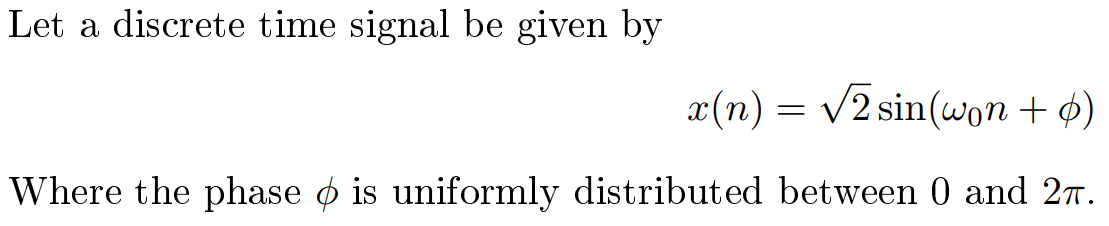

clear variables;

### [✔] 1) Determine the autocorrelation function for *x*(*n*)

The autocorrelation function of a real **sine signal** $z\left(n\right)=A\;\mathrm{sin}\left(\omega n+\phi \right)$ where $A$ and $\omega$ are real constants and $\phi ~U\left(0,2\pi \right)$ is:

        
$$r_{\textrm{zz}} \left(\ell \right)=-\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)$$


As $A=\sqrt{2}$, we have:

        
$$r_{\textrm{xx}} \left(\ell \right)=-\frac{{\left(\sqrt{2}\right)}^2 }{2}\cos \left(\omega_0 \ell \right)$$


        
$$r_{\textrm{xx}} \left(\ell \right)=-\cos \left(\omega_0 \ell \right)$$


### [?] 2) Determine the 2nd order forward linear prediction filter

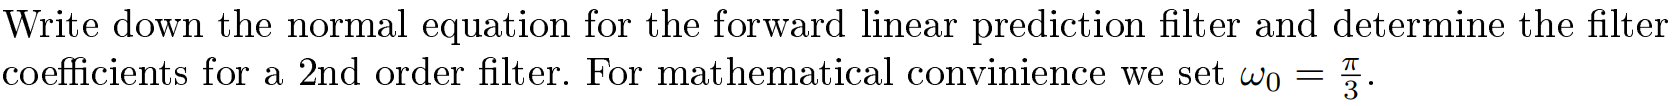

The forward linear predictor can predict "future" sample $x\left(n\right)$ given the previous $p$ samples         $x\left(n-1\right),x\left(n-2\right),\cdots ,x\left(n-p\right)$. Such an predictor can be modelled as a FIR filter:

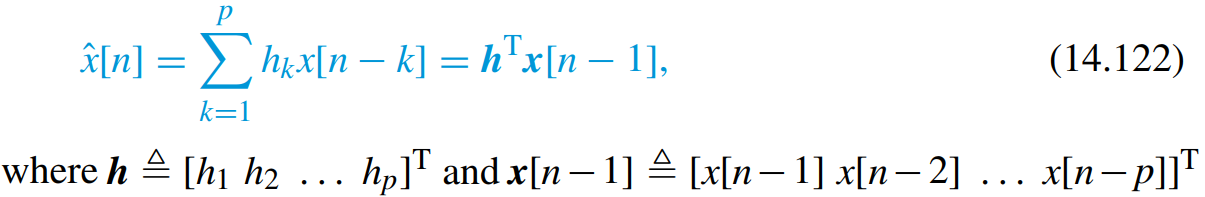

The normal equation for the optimum $p$'th order linear predictor is given by Eq. 14.125:

        

The normal equation for the second order filter is:

        
$$\left\lbrack \begin{array}{cc}
r_{\mathrm{xx}} \left(0\right) & r_{\mathrm{xx}} \left(1\right)\\
r_{\mathrm{xx}} \left(1\right) & r_{\mathrm{xx}} \left(0\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
h_1 \\
h_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
r_{\mathrm{xx}} \left(1\right)\\
r_{\mathrm{xx}} \left(2\right)
\end{array}\right\rbrack$$


M = 2;
w0 = pi/3;
ell = 1:M+1;

r_xx = -cos(w0*ell);
R = toeplitz(r_xx(1:M));
r = r_xx(2:M+1)';
h_opt = R\r

h_opt = 	1.0e+15 *

   -2.2365
   -2.2365


*[?] The coefficients seem too large.*

### [»] 3) Find the system function for the filter and locate the zeros

        
$$H\left(z\right)=h_1 z^{-1} +h_2 z^{-2}$$


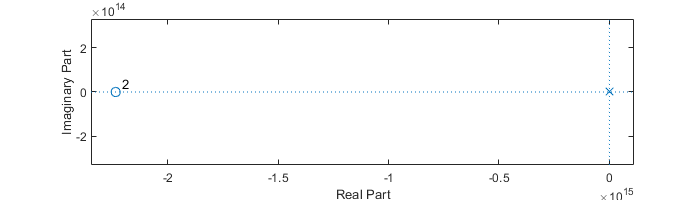

zplane(h_opt, 1)

### [»] 4) Determine the frequency response, plot it and comment on the result

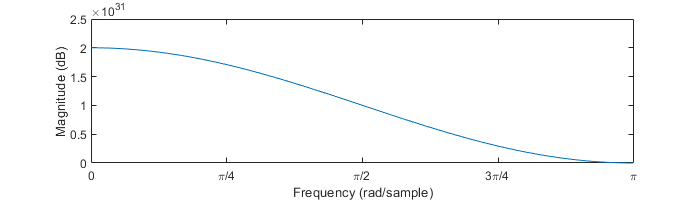

[H, w] = freqz(h_opt, 1);
plot(w, H.*conj(H));
set(gca,'XTick', 0:pi/4:pi)
set(gca,'XTickLabel', {'0','\pi/4','\pi/2','3\pi/4','\pi'})
xlabel('Frequency (rad/sample)')
ylabel('Magnitude (dB)')
xlim([0, pi]);

### [»] 5) Calculate the prediction error

The minimum square error for an optimum linear predictor is given by Eq. 14.127:

        

r_xx(1)

ans = -0.5000

mse = r_xx(1) - h_opt'*r

mse = 3.3547e+15

## [?] ADSI Problem 6.8: Autocorrelation function and linear prediction

*Assume that for a given sequence of data *$\left\lbrace x\left(n\right)\right\rbrace$* the autocorrelation function has been calculated and used to solve the normal equations so that the optimum p'th order linear predictor was found. Now, an amplifier is placed in the signal chain so that the signal is *$\left\lbrace c\cdot x\left(n\right)\right\rbrace$*. How does the autocorrelation function and the linear predictor change?*

In this problem, the autocorrelation function $r_{\mathrm{xx}} \left(\ell \right)$ is already computed for signal $x\left(n\right)$.

We want to find the autocorrelation function for the amplified signal $y\left(n\right)=c\cdot x\left(n\right)$:

        
$$r_{\mathrm{yy}} \left(\ell \right)=E\left\lbrack y\left(n\right)y\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack c\;x\left(n\right)\;c\;x\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{yy}} \left(\ell \right)=c^2 E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{yy}} \left(\ell \right)=c^2 \;r_{\mathrm{xx}} \left(\ell \right)$$


So, the autocorrelation sequence of the amplified signal is multiplied by $c^2$

The normal equation for the optimum linear predictor is given by Eq. 14.125:

        

Even when the autocorrelation sequence is multiplied by some factor, the impulse response of the linear predictor $\mathit{\mathbf{h}}$ will remain the same. Therefore, the linear predictor will still work the same way.

***[?] Are there other explanations?***